I = imread('kit-chemie.jpg');
I = imresize(I, [50 NaN]);
[rows, cols, ~] = size(I);

[d, n] = size(X);

n^(-0.2)

ans = 0.1928

mean(X, 2)

ans =     0.0000
   -0.0000
   -0.0000
    0.5100
    0.5067


std(X, [], 2)

ans =     1.0001
    1.0001
    1.0001
    0.2887
    0.2887


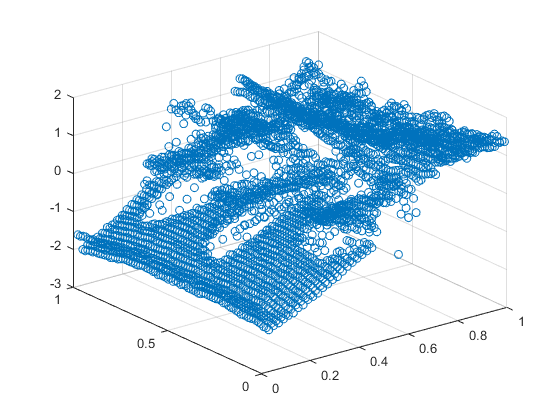

scatter3(X(4,:), X(5,:), X(2,:))

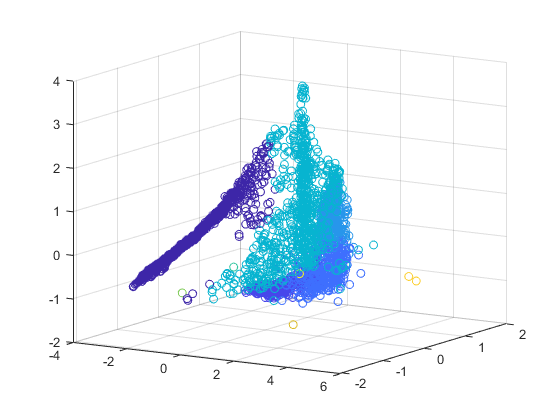

scatter3(X(1,:), X(2,:), X(3,:), [], A)

[X, w, h, m, s] = image_transform(I);
[A, C, T] = mean_shift3(X, 0.6, 0.1);

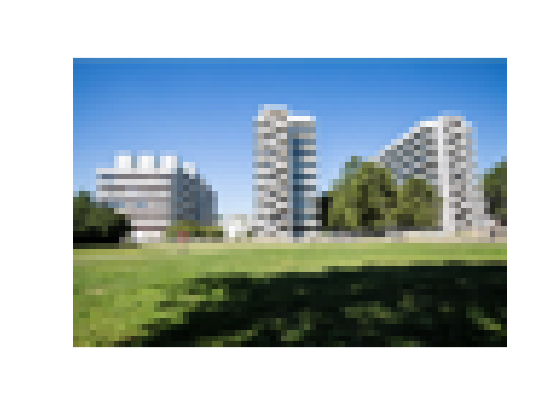

figure
imshow(I, 'InitialMagnification', 'fit');

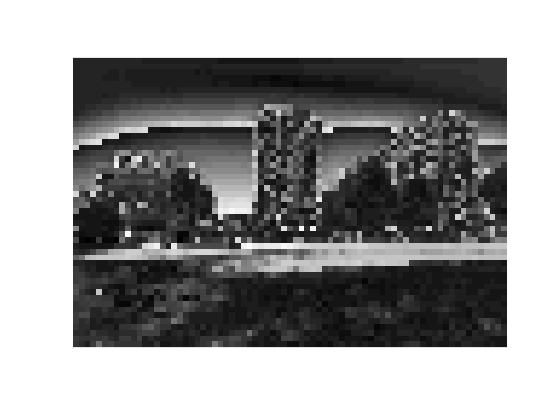

figure
imshow(reshape(T, rows, cols), [], 'InitialMagnification', 'fit');

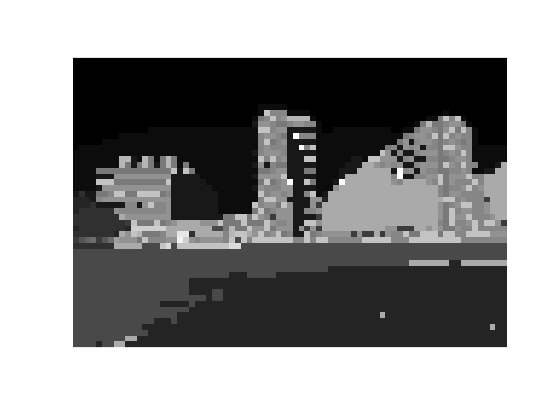

figure
imshow(reshape(A, rows, cols), [], 'InitialMagnification', 'fit');

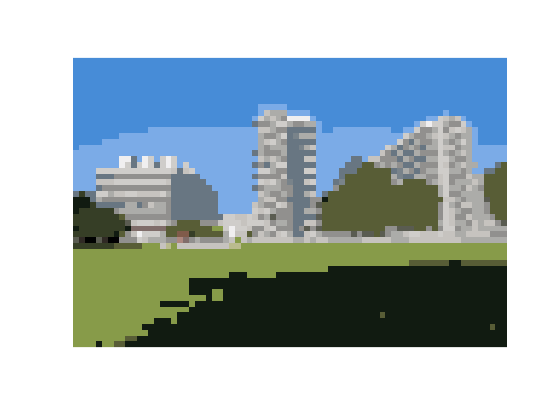

figure
imshow(image_inverse_transform(C(:,A), w, h, m, s), [], 'InitialMagnification', 'fit');

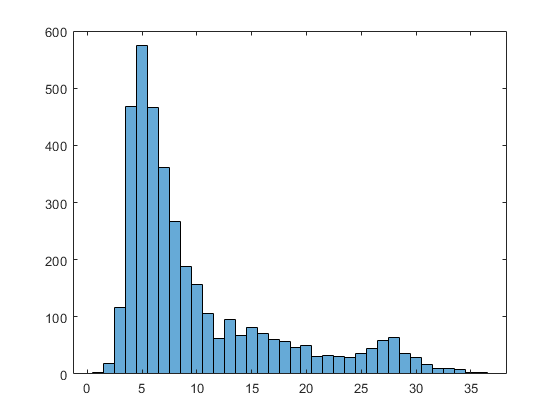

histogram(T)

exp(-0.5 * sum(((X - X(:,1)) / 0.4).^2, 1))

ans =     1.0000    0.5585    0.6914    0.7502    0.8247    0.8484    0.7442    0.6590    0.5216    0.3406    0.1875    0.0991    0.0389    0.0128    0.0041    0.0014    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



sum(((X - X(:,1)) / 0.4).^2, 1) < 1

ans = 1×3750 logical array
   1   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
